clear; clc; close all;

restoredefaultpath;
addpath("../spm/"); % Add path for SPM
spm('defaults','FMRI');
spm_jobman('initcfg');

## DCM for fMRI - 2nd level (Motor)

dirGLM = '/Users/abhijitc/Documents/Abhijit/LenaLab_DCM/SPM2_Motor/peb_motor/';

load(fullfile(dirGLM, "participants.mat"));

## PEB specification

clear matlabbatch;
matlabbatch{1}.spm.dcm.peb.specify.name = 'Motor';
matlabbatch{1}.spm.dcm.peb.specify.model_space_mat = {fullfile(dirGLM,'GCM_tak.mat')};
matlabbatch{1}.spm.dcm.peb.specify.dcm.index = 1;
matlabbatch{1}.spm.dcm.peb.specify.cov.design_mtx.cov_design = X;
matlabbatch{1}.spm.dcm.peb.specify.cov.design_mtx.name = Xnames;
matlabbatch{1}.spm.dcm.peb.specify.fields.default = {'A','B'}';
matlabbatch{1}.spm.dcm.peb.specify.priors_between.components = 'Single';
matlabbatch{1}.spm.dcm.peb.specify.priors_between.ratio = 16;
matlabbatch{1}.spm.dcm.peb.specify.priors_between.expectation = 0;
matlabbatch{1}.spm.dcm.peb.specify.priors_between.var = 0.0625;
matlabbatch{1}.spm.dcm.peb.specify.priors_glm.group_ratio = 1;
matlabbatch{1}.spm.dcm.peb.specify.estimation.maxit = 64;
matlabbatch{1}.spm.dcm.peb.specify.show_review = 0;
spm_jobman('run',matlabbatch); 



------------------------------------------------------------------------
15-Jul-2025 18:16:21 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 18:16:21 - Running 'Specify / Estimate PEB'
VL Iteration 1       : F = -2537222.09 dF: 0.0000  [-3.75]
VL Iteration 2       : F = -2511801.67 dF: 25420.4171  [-3.50]
VL Iteration 3       : F = -2487008.61 dF: 24793.0638  [-3.25]
VL Iteration 4       : F = -2464290.31 dF: 22718.2970  [-3.00]
VL Iteration 5       : F = -2444872.27 dF: 19418.0351  [-2.75]
VL Iteration 6       : F = -2429400.62 dF: 15471.6548  [-2.50]
VL Iteration 7       : F = -2417739.02 dF: 11661.5949  [-2.25]
VL Iteration 8       : F = -2409078.13 dF: 8660.8977  [-2.00]
VL Iteration 9       : F = -2402323.69 dF: 6754.4391  [-1.75]
VL Iteration 10      : F = -2396488.93 dF: 5834.7597  [-1.50]
VL Iteration 11      : F = -2390820.17 dF: 5668.7566  [-1.25]
VL Iteration 12      : F = -2384666.02 dF: 6154.1470  [-1.00]
VL Iteratio

## Bayesian model comparison



------------------------------------------------------------------------
15-Jul-2025 18:24:07 - Running job #2
------------------------------------------------------------------------
15-Jul-2025 18:24:07 - Running 'Compare / Average PEB models'
BMC: 100% 
1 models in Occams window:
	Model 1, p(m|Y)=1.00
Averaging models in Occams window...


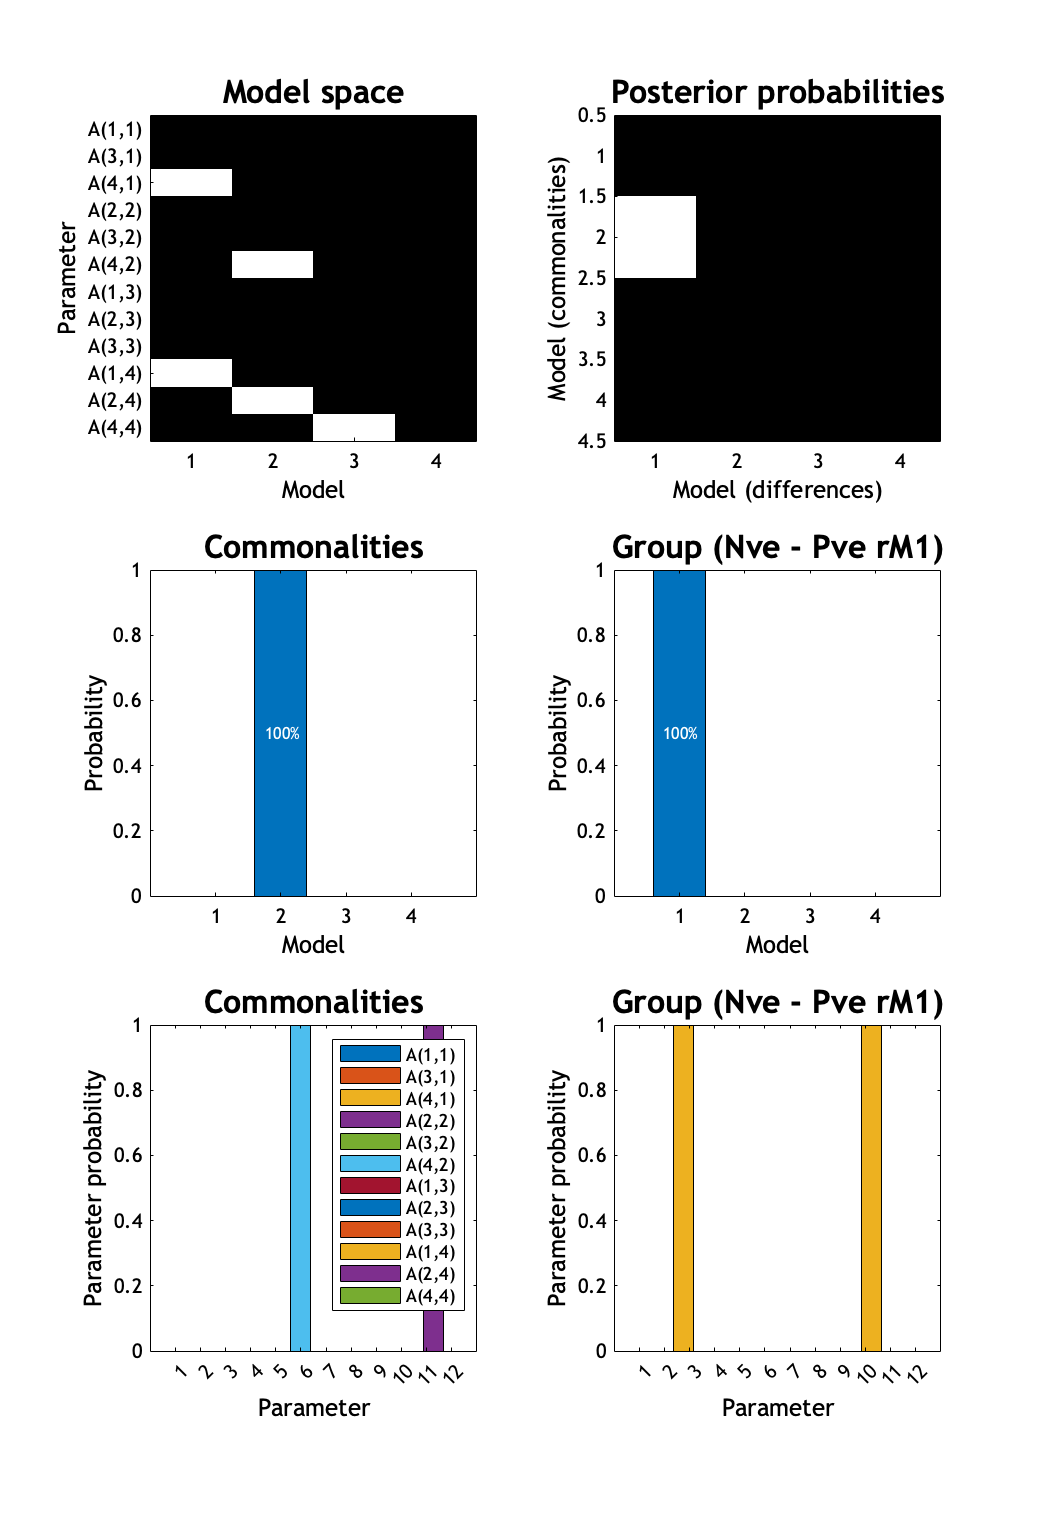

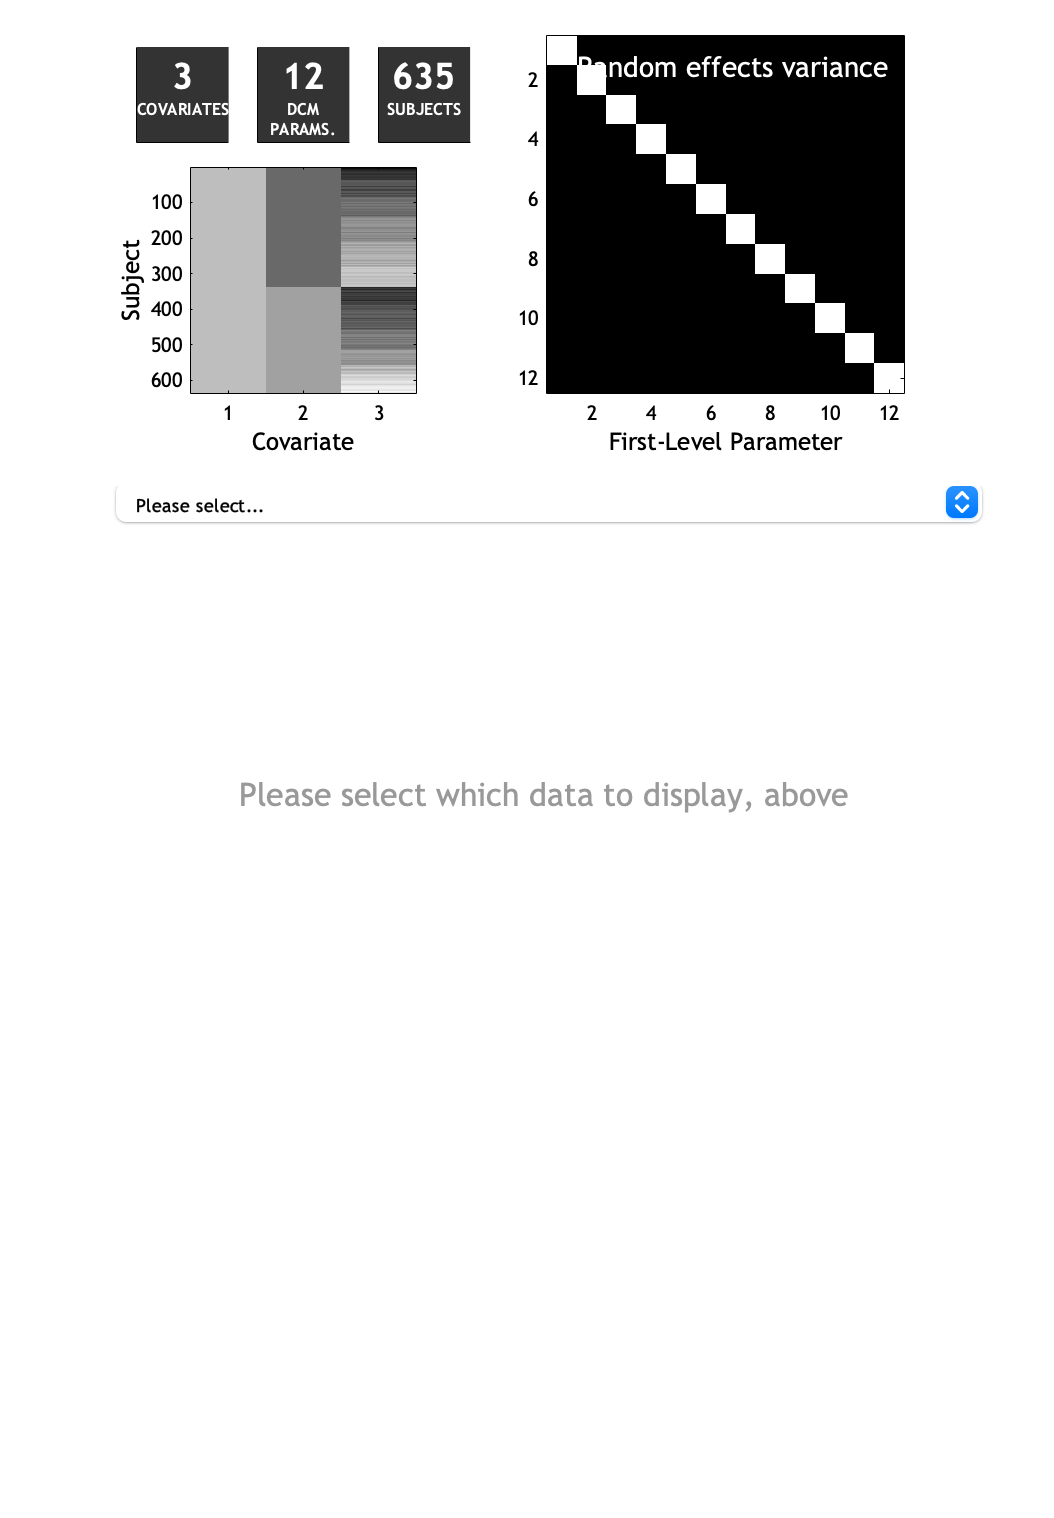

15-Jul-2025 18:24:18 - Done    'Compare / Average PEB models'
15-Jul-2025 18:24:18 - Done



clear matlabbatch;
matlabbatch{1}.spm.dcm.peb.compare.peb_mat = {fullfile(dirGLM,'PEB_Motor.mat')};
matlabbatch{1}.spm.dcm.peb.compare.model_space_mat = {fullfile(dirGLM,'GCM_templates.mat')}; 
matlabbatch{1}.spm.dcm.peb.compare.show_review = 1;
spm_jobman('run',matlabbatch); 